# **Laboratory 1A: Pre-SiSy Math Exercises**

## **Thema-1**** : Functions with fractions**

(1)  Simplify the compound fraction (“Doppelbruch”) in the expression below:

                                
$$f(x) = \frac{1}{1+\frac{1}{1+x}}$$
                      

   *  Solution: *$f(x) = \frac{1+x}{2+x}$

(2) Calculate the following limit cases for the function f(x) from exercise (1): 

     
$$for \quad 0<x<<1  \Rightarrow f(x) \approx \frac{1}{2}

$$



$$for \quad x>>1  \Rightarrow f(x) \approx {1}$$


 Write a Matlab script generating a plot of f(x) for   $x \in$  $  {10^{-3},10^{+3}}\brack$  

Use the function *logspace* to define a vector x. 

Check the syntax of this function with the help in Matlab.

clear all,close all, clc
display('Lab1A:exercise 2')

Lab1A:exercise 2


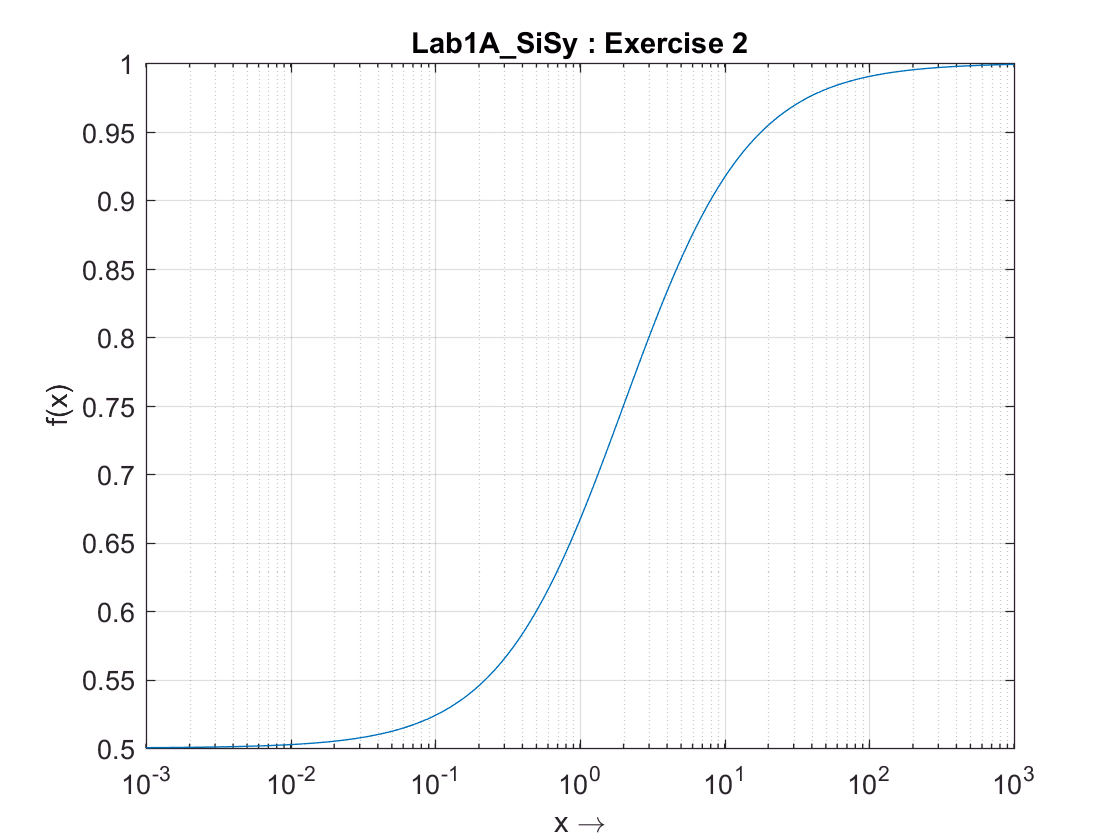


% PARAMETERS
x = logspace(-3,+3,200);
f_x = (1+x)./(2+x);

% PLOT
figure(1)
semilogx(x,f_x),grid on
    title('Lab1A\_SiSy : Exercise 2')
    xlabel('x \rightarrow')
    ylabel('f(x)')

## Thema-2 : Complex Numbers (specially polar notation with Euler’s identity)

(3)	Determine the Cartesian notation of the following complex numbers:

                  
$$z_1=2\cdot exp (j\frac{\pi}{2})= 2 \cdot e^{+j\frac{\pi}{2}} =+2 \cdot j$$



$$z_2=1 \cdot exp (-j \pi ) = -1$$


       
$$z_3 = \sqrt{2}  \cdot exp (-j \frac {\pi} {4}  ) = 1-j$$


(4)	Determine the polar notation of the following complex numbers:

 	Hint: draw them as a vector in a complex plane

     
$$z_4 = 1+ j \cdot 1=   \sqrt{2}  \cdot exp (+j \frac {\pi} {4}  ) $$


         
$$z_5 = -1+ j \cdot 1=   \sqrt{2}  \cdot exp (+j \frac {3\pi} {4}  ) $$



$$z_6 = -j \cdot 3 =   +3  \cdot exp (-j \frac {\pi} {2}  ) $$


Find out the Matlab conversion functions that allow you to verify your results from exercises 3 & 4. 

clear all,close all, clc
display('Lab1A:exercise 3&4')

Lab1A:exercise 3&4



% SYNTAX (checked with help) :   [X,Y] = pol2cart(TH,R)
[x1,y1] = pol2cart(pi/2,2)   % check numerical error approx to "zero"

x1 = 1.2246e-16

y1 = 2

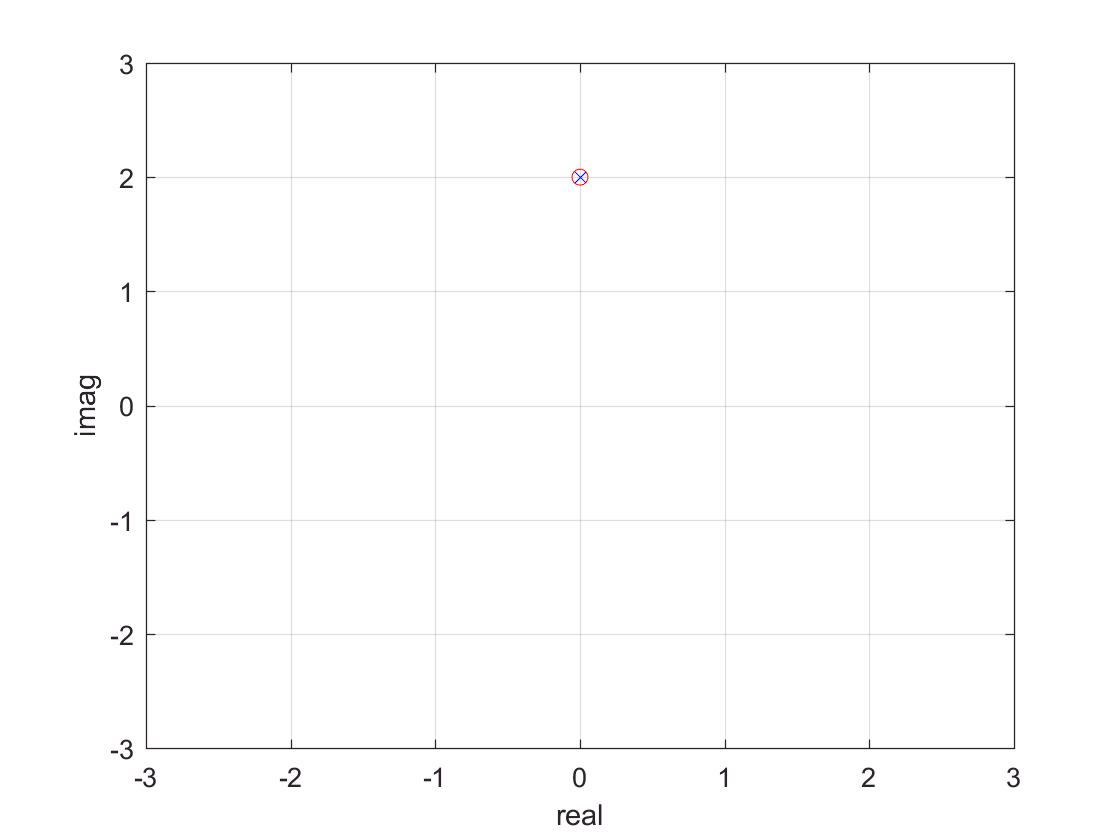

z1 = x1+j*y1;
plot(x1,y1,'xb'), grid on, hold on, xlabel('real'),ylabel('imag')
plot(z1,'or'), hold off, axis([-3 3 -3 3])

% similar to other complex numbers 

(5)	Open, execute and understand the code of the Matlab script presisy_auf5.m 

Make the necessary changes, such that you generate a plot showing a spiral with four windings (Spiralwicklung). 

clear all,close all, clc
display('Lab1A:exercise 5')

Lab1A:exercise 5


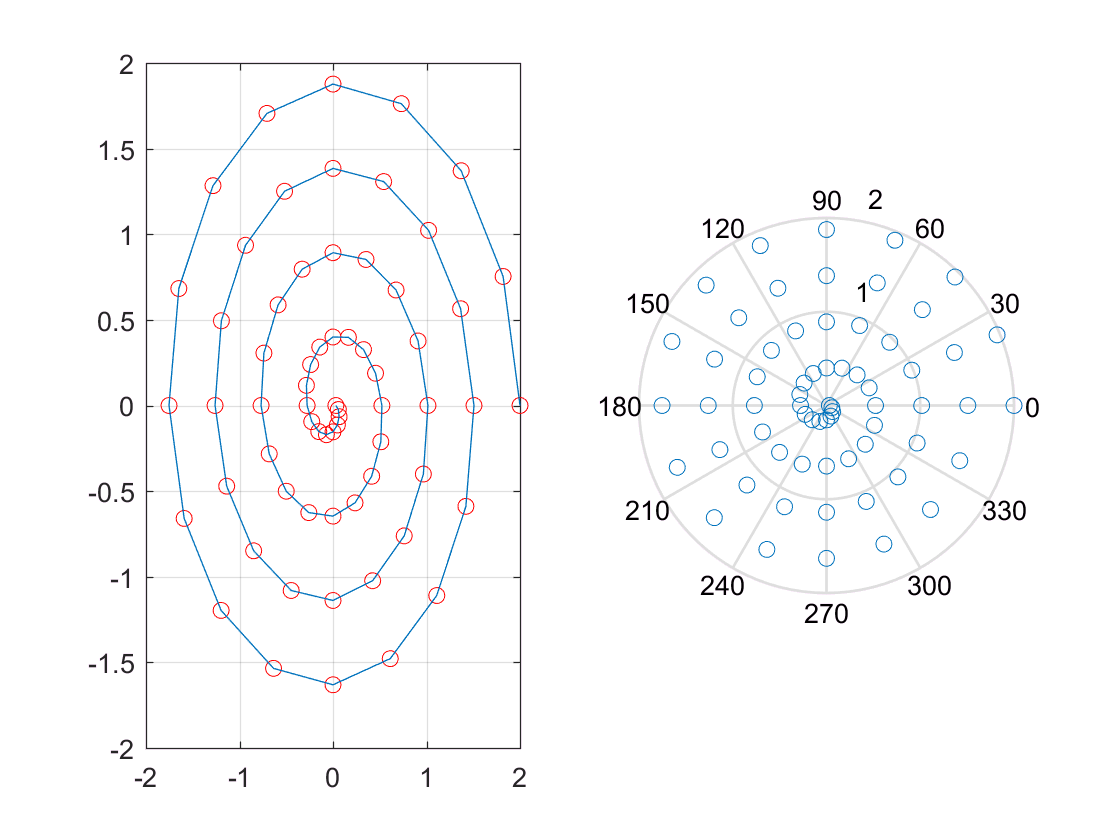


N = 4;              % number of windings
theta=0:pi/8:N*2*pi;

M = length(theta);
aux = 1:-1/M:1/M;
rho = 2*aux;
z1 = rho.*exp(j*theta);

subplot(121),plot(z1,'ro'),grid on, hold on
              plot(z1),grid on, hold off
              subplot(122),polar(angle(z1),abs(z1),'o'),grid on

(6) Determine the polar notation of the following complex numbers:

            *Hint: Please do not use the method of multiplication with the conjugated complex,*

             *but rather calculate the polar notation for both numerator and denominator*

*Solution*


$$z_7 = \frac{1}{ -j \cdot 3} = 
\frac{1}{3} \cdot \frac{1}{exp (-j \frac {\pi} {2})}  = 
\frac{1}{3} \cdot {exp (j \frac {\pi} {2})} =
j \cdot \frac{1}{3} $$



$$z_8 = \frac{1}{ -1+j} = 
\frac{1}{\sqrt{2}} \cdot e^{-j \frac{3\pi}{4}}=
\frac{-1-j}{2}$$



$$z_9 = \frac{-1+j}{ 1+j} = e^{j \frac{\pi}{2}}=j$$


(7) Given the complex function  $f(x)= 1+j \cdot x$    , determine the value of x for which:

*a.             *$\vert f(x) \vert = abs \{f(x)\}=\sqrt{2}$

b.             $\langle f(x) = phase \{ f(x) \} = +45°$

(7) *Solution*

    a) $x=1$

    b) $x=1$

8) What is the value of the magnitude and phase of the complex function    $g(x) = \frac {1} {1+j \cdot x}$   , when x=1:

a.             $\vert g(x) \vert = abs \{g(x)\}= ...$  

b.             $\langle g(x) = phase \{ g(x) \} = ...$

8) *Solution*

    a) $\frac{1}{\sqrt{2}}$

    b) $\frac{-\pi}{4}$

## Thema-3: Trigonometric Functions 

(9)	& (10)    *Solution*

Verify your sketch by generating the same plot in Matlab. 

clear all,close all, clc
display('Lab1A:exercise 9&10')

Lab1A:exercise 9&10


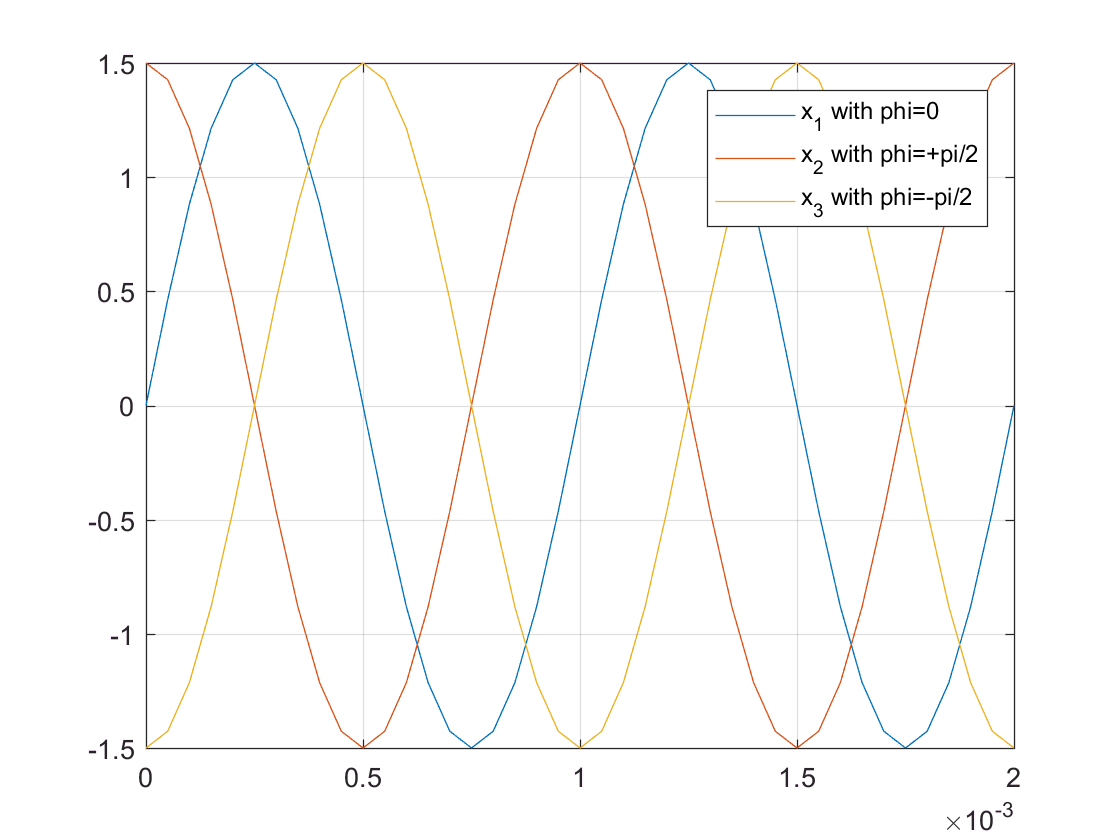


% PARAMETERS
A = 1.5;
f0 = 1e3;
phi = [0 +pi/2 -pi/2];

T0 = 1/f0;
tstep = T0/20;
t = 0:tstep:2*T0;

x1_t = A*sin(2*pi*f0*t + phi(1));
x2_t = A*sin(2*pi*f0*t + phi(2));
x3_t = A*sin(2*pi*f0*t + phi(3));

% PLOTS
plot(t,x1_t,t,x2_t,t,x3_t),grid on 
    legend('x_1 with phi=0','x_2 with phi=+pi/2','x_3 with phi=-pi/2')

## Thema-4 : Function description using the sum-sign

(11)	 *Solution         *$x(t) = 2 + 
\frac{1}{2} \cdot cos(2\pi f_0t) +
\frac{3}{2} \cdot cos(2\pi 3f_0t + \pi) $

(12)	and (13) Try it out the conv operation with the comb-function to get shifted copies of the original y(t) !

clear all, close all
display('Lab-1A: Exercise 12 & 13')

Lab-1A: Exercise 12 & 13


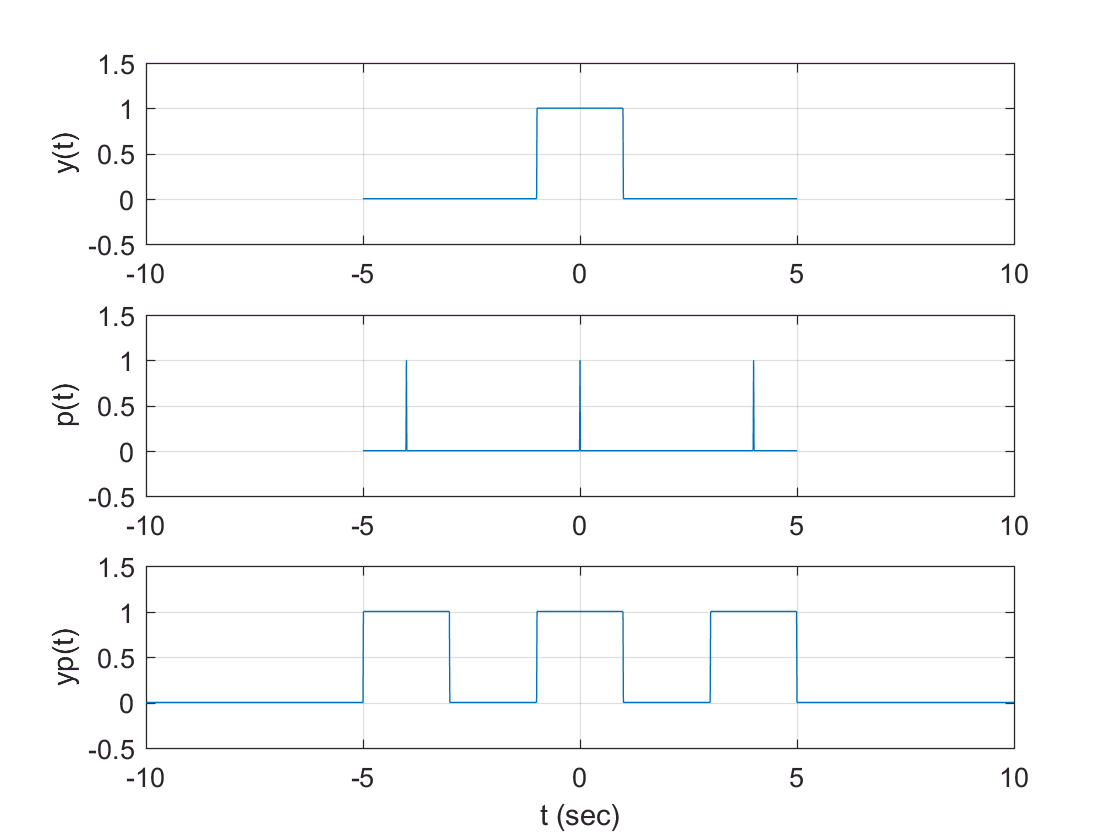


tstep = 1e-2;
t = -5:tstep:5;
t_long = -10:tstep:10;

y_t = double( abs(t)<1 );
p_t = double( (t==-4) | (t==0) | (t==4) );
yp_t = conv(y_t,p_t);

subplot(311), plot (t,y_t),grid on, ylim([-0.5 1.5]), xlim([-10 10]), ylabel('y(t)')
subplot(312), plot (t,p_t),grid on, ylim([-0.5 1.5]), xlim([-10 10]), ylabel('p(t)')
subplot(313), plot (t_long,yp_t),grid on, ylim([-0.5 1.5]), xlim([-10 10]), ylabel('yp(t)')
             xlabel('t (sec)')

## **Thema-5**** : Integration and Differentiation of exponential-function**

(14) *Solution*

a.     $\int e^{at}dt = 
\frac{1}{a} e^{at} + C$                                     

b.     $\frac{d(e^{at})}{dt} =
a \cdot e^{at} $      

c.     $\int _0 ^t      e^{a \lambda} d\lambda = 
\frac{1}{a} \left[ e^{at} -1 \right]$

## **Thema-6**** : Graphical solution for Integrals**  (as area under the curve)

(15) *Solution: integral approximation with cumsum*tstep*

clear all,close all, clc
display('Lab1A:exercise 15')

Lab1A:exercise 15


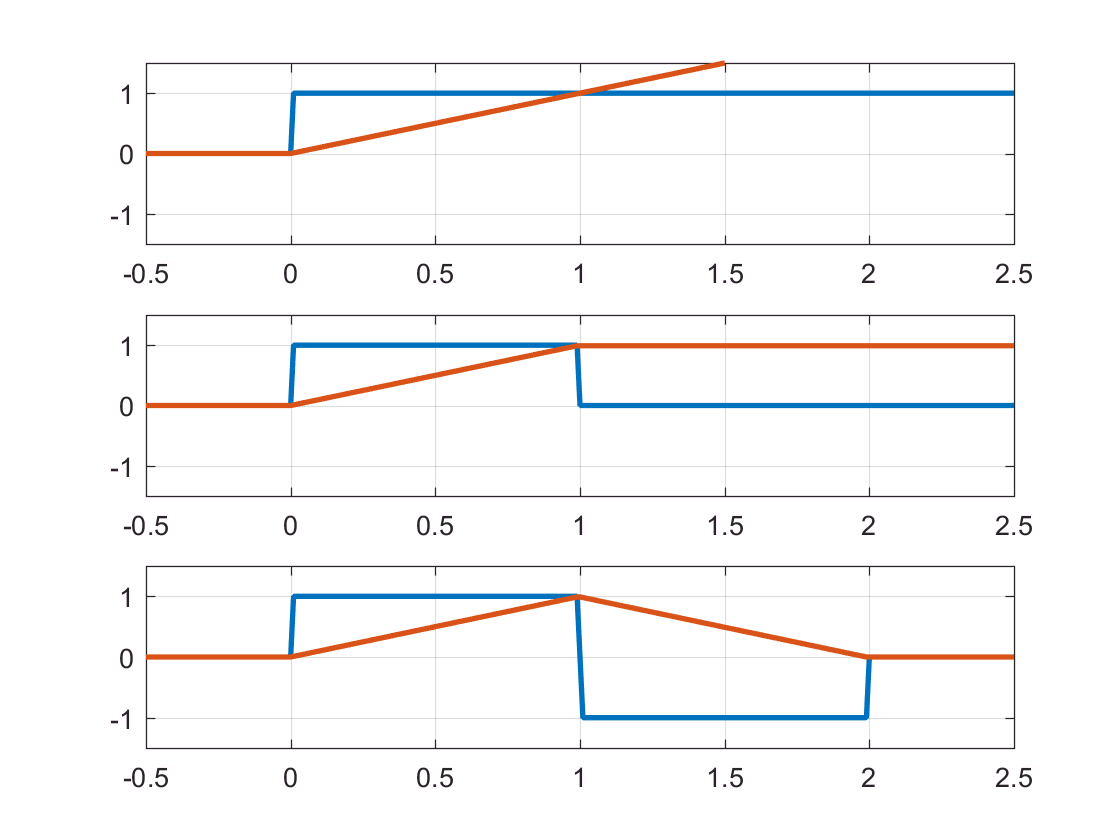


% PARAMETERS
tstep = 1/100;
t = -0.5:tstep:2.5;

x1_t = double(t>0);
y1_t = cumsum(x1_t*tstep);

x2_t = double( (t>0) & (t<1) );
y2_t = cumsum(x2_t*tstep);

x3_t = x2_t - double( (t>1) & (t<2) );
y3_t = cumsum(x3_t*tstep);

figure()
subplot(311)
    plot(t,x1_t,'LineWidth',2),grid on, hold on
    plot(t,y1_t,'LineWidth',2),grid on
    ylim([-1.5 1.5])
subplot(312)
    plot(t,x2_t,'LineWidth',2),grid on, hold on
    plot(t,y2_t,'LineWidth',2),grid on
    ylim([-1.5 1.5])   
subplot(313)
    plot(t,x3_t,'LineWidth',2),grid on, hold on
    plot(t,y3_t,'LineWidth',2),grid on
    ylim([-1.5 1.5])    

## **Thema-7**** : Plots in log-log scale**

 (16) Solution

    for    $ 0<x<<1  \Rightarrow f(x) \approx 1

$

    for    $x >> 1  \Rightarrow f(x) \approx \frac{1}{x}

$

possibly     $ f(x) = \frac{1}{1+x}

$      

display('Lab1A:exercise 16')

Lab1A:exercise 16


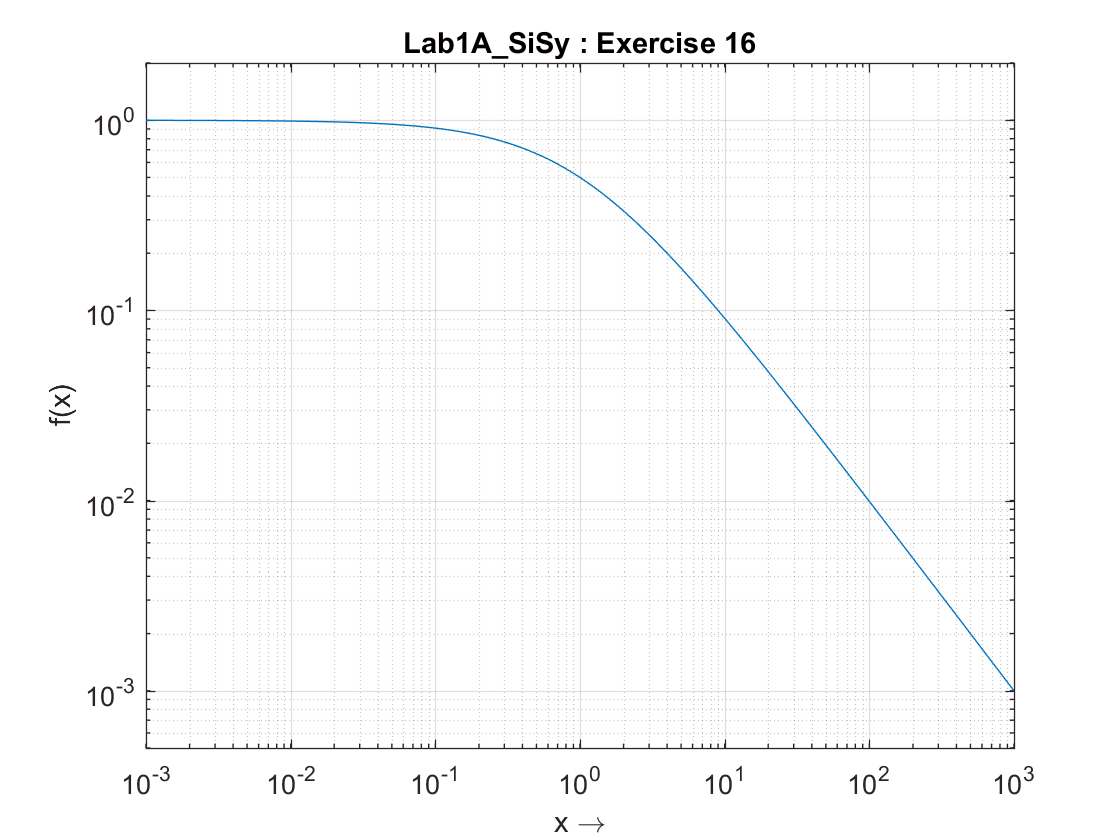


% PARAMETERS
x = logspace(-3,+3,200);
f_x = 1./(1+x);

% PLOT
figure()
loglog(x,f_x),grid on
    title('Lab1A\_SiSy : Exercise 16'), ylim([5e-4 2])
    xlabel('x \rightarrow'), ylabel('f(x)')

## Thema-8 : Logarithm of basis 10

(17)	Determine the value of the following logarithmic expressions:

a.		$log_{10} (10^n) = n$ 

b.		 $log_{10}  \left( {\frac {10^n} {10^p} } \right) = n-p$ 

c.		$log_{10} (2^n) = n \cdot (0.3)$  	given   $log_{10} (2) \cong  0.3$

d.		 $20 \cdot log_{10} (2) \cong  6.0$

e.		 $20 \cdot log_{10} \left( \frac{1}{2} \right)
 \cong  -6.0$

Check your results in Matlab, using the function log10 which calculates the logarithm with basis 10. 

% log10(X) is the base 10 logarithm of the elements of X